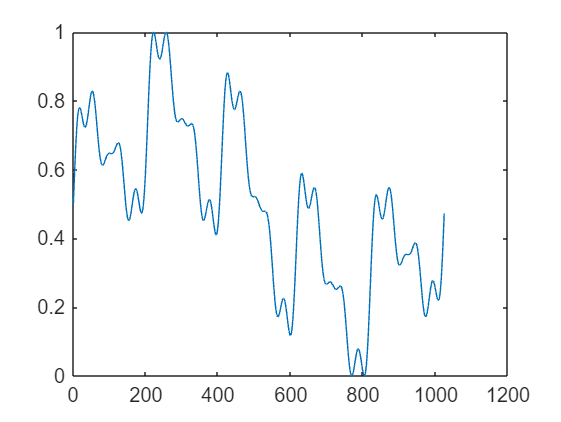

clear all

% Generating multisine
f_i = [1,5,10,20,25];
U_i = [0.5,0.4,0.2,0.1,0.1];

N = 16;

dt = 1/1024;
t = [0:dt:1/f_i(1)-dt];

y_temp = 0;
for i = 1:length(f_i)
    y_temp = y_temp + U_i(i)*sin(2*pi*f_i(i)*t);
end

y = (y_temp+1)*1/2;
plot(y)

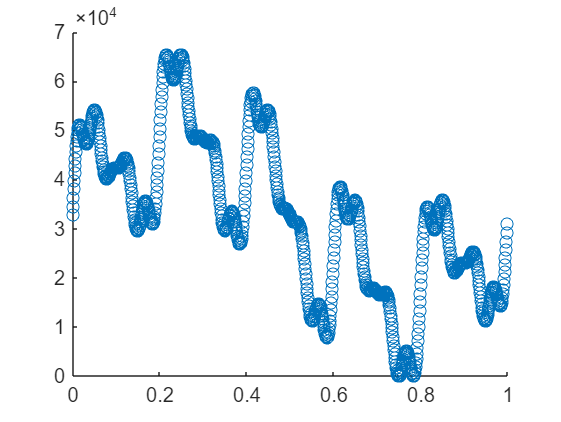


y_hex = floor(y*(2^N-1));
scatter(t,y_hex)


hex_sine = dec2hex(y_hex)

hex_sine = 1024×4 char array
    '7FFF'
    '870D'
    '8E08'
    '94DB'
    '9B75'
    'A1C4'
    'A7B8'
    'AD42'
    'B257'
    'B6EB'
    'BAF7'
    'BE76'
    'C165'
    'C3C4'
    'C595'
    'C6DD'
    'C7A3'
    'C7F0'
    'C7CF'
    'C74E'
    'C67A'
    'C563'
    'C418'
    'C2AA'
    'C12A'
    'BFA6'
    'BE2F'
    'BCD2'
    'BB9C'
    'BA9A'
    'B9D4'
    'B952'
    'B919'
    'B92E'
    'B991'
    'BA42'
    'BB3D'
    'BC7D'
    'BDFC'
    'BFB0'
    'C190'
    'C390'
    'C5A4'
    'C7BF'
    'C9D4'
    'CBD5'
    'CDB7'
    'CF6C'
    'D0E9'
    'D224'
    'D314'
    'D3B1'
    'D3F5'
    'D3DD'
    'D366'
    'D290'
    'D15E'
    'CFD1'
    'CDF0'
    'CBC2'
    'C94E'
    'C69F'
    'C3BE'
    'C0B8'
    'BD97'
    'BA68'
    'B737'
    'B411'
    'B0FF'
    'AE0D'
    'AB44'
    'A8AE'
    'A650'
    'A431'
    'A256'
    'A0C0'
    '9F72'
    '9E6C'
    '9DAB'
    '9D2C'
    '9CED'
    '9CE6'
    '9D13'
    '9D6B'
    '9DE9'
    '9E85'
    '9F35'
    '9FF4'
   

MSB = bitshift(y_hex,-8) 

MSB =    127   135   142   148   155   161   167   173   178   182   186   190   193   195   197   198   199   199   199   199   198   197   196   194   193   191   190   188   187   186   185   185   185   185   185   186   187   188   189   191   193   195   197   199   201   203   205   207   208   210


msb_sine = "0x"+string(dec2hex(MSB))

msb_sine = 1024×1 string array
    "0x7F"
    "0x87"
    "0x8E"
    "0x94"
    "0x9B"
    "0xA1"
    "0xA7"
    "0xAD"
    "0xB2"
    "0xB6"
    "0xBA"
    "0xBE"
    "0xC1"
    "0xC3"
    "0xC5"
    "0xC6"
    "0xC7"
    "0xC7"
    "0xC7"
    "0xC7"
    "0xC6"
    "0xC5"
    "0xC4"
    "0xC2"
    "0xC1"
    "0xBF"
    "0xBE"
    "0xBC"
    "0xBB"
    "0xBA"


lsb_sine = "0x"+string(dec2hex(y_hex-MSB*2^8))

lsb_sine = 1024×1 string array
    "0xFF"
    "0x0D"
    "0x08"
    "0xDB"
    "0x75"
    "0xC4"
    "0xB8"
    "0x42"
    "0x57"
    "0xEB"
    "0xF7"
    "0x76"
    "0x65"
    "0xC4"
    "0x95"
    "0xDD"
    "0xA3"
    "0xF0"
    "0xCF"
    "0x4E"
    "0x7A"
    "0x63"
    "0x18"
    "0xAA"
    "0x2A"
    "0xA6"
    "0x2F"
    "0xD2"
    "0x9C"
    "0x9A"



mcu_sin = [msb_sine,lsb_sine]

mcu_sin = 1024×2 string array
    "0x7F"    "0xFF"
    "0x87"    "0x0D"
    "0x8E"    "0x08"
    "0x94"    "0xDB"
    "0x9B"    "0x75"
    "0xA1"    "0xC4"
    "0xA7"    "0xB8"
    "0xAD"    "0x42"
    "0xB2"    "0x57"
    "0xB6"    "0xEB"
    "0xBA"    "0xF7"
    "0xBE"    "0x76"
    "0xC1"    "0x65"
    "0xC3"    "0xC4"
    "0xC5"    "0x95"
    "0xC6"    "0xDD"
    "0xC7"    "0xA3"
    "0xC7"    "0xF0"
    "0xC7"    "0xCF"
    "0xC7"    "0x4E"
    "0xC6"    "0x7A"
    "0xC5"    "0x63"
    "0xC4"    "0x18"
    "0xC2"    "0xAA"
    "0xC1"    "0x2A"
    "0xBF"    "0xA6"
    "0xBE"    "0x2F"
    "0xBC"    "0xD2"
    "0xBB"    "0x9C"
    "0xBA"    "0x9A"


mcu_sin_reshaped = reshape(mcu_sin',1,[])

mcu_sin_reshaped = 1×2048 string array
    "0x7F"    "0xFF"    "0x87"    "0x0D"    "0x8E"    "0x08"    "0x94"    "0xDB"    "0x9B"    "0x75"    "0xA1"    "0xC4"    "0xA7"    "0xB8"    "0xAD"    "0x42"    "0xB2"    "0x57"    "0xB6"    "0xEB"    "0xBA"    "0xF7"    "0xBE"    "0x76"    "0xC1"    "0x65"    "0xC3"    "0xC4"    "0xC5"    "0x95"    "0xC6"    "0xDD"    "0xC7"    "0xA3"    "0xC7"    "0xF0"    "0xC7"    "0xCF"    "0xC7"    "0x4E"    "0xC6"    "0x7A"    "0xC5"    "0x63"    "0xC4"    "0x18"    "0xC2"    "0xAA"    "0xC1"    "0x2A"    "0xBF"    "0xA6"    "0xBE"    "0x2F"    "0xBC"    "0xD2"    "0xBB"    "0x9C"    "0xBA"    "0x9A"    "0xB9"    "0xD4"    "0xB9"    "0x52"    "0xB9"    "0x19"    "0xB9"    "0x2E"    "0xB9"    "0x91"    "0xBA"    "0x42"    "0xBB"    "0x3D"    "0xBC"    "0x7D"    "0xBD"    "0xFC"    "0xBF"    "0xB0"    "0xC1"    "0x90"    "0xC3"    "0x90"    "0xC5"    "0xA4"    "0xC7"    "0xBF"    "0xC9"    "0xD4"    "0xCB"    "0xD5"    "0xCD"    "0xB7"    "0xCF"    "0x6C" 

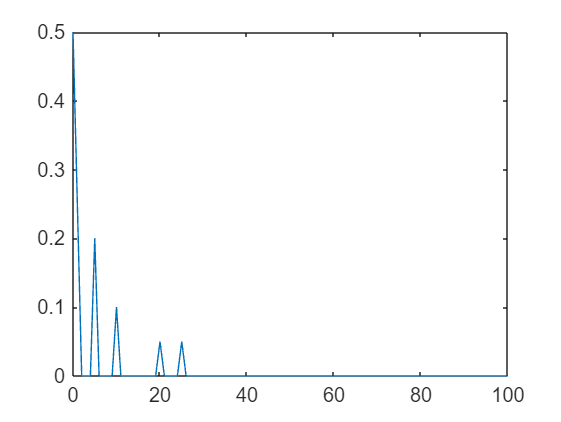


%writing to file for MCU
folder = "C:\Users\Peter\STM32CubeIDE\workspace_1.12.0\RedPill_DAC_SPI_MultiSin_FFT\Core\Src\";
fid = fopen(folder+"dacMultiSine.txt",'wt');
fprintf(fid,'%s,', mcu_sin_reshaped{1:end-1});
fprintf(fid,'%s', mcu_sin_reshaped{end});
fclose(fid);

% Spectre of generated signal
Y = abs(fft(y))/length(t);
df = (1/(length(t)*dt));
f = [0:df:(1/dt)-df];
f_egy = f(1:end/2);
Y(2:end) = 2*Y(2:end);
Y_egy = Y(1:end/2);
plot(f_egy,Y_egy)
xlim([0,100])

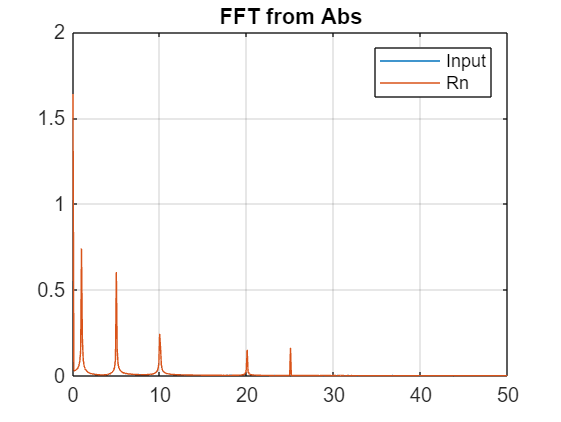

% Spectre of measured signal: Input signal, Rn signal, Impedance signal,
% Uz/Un amplitude spectre
clear all
T = readtable('absSpectres.csv');
Y_in_a = T{:,1};
Y_imp_a = T{:,2};
Y_ref_a = T{:,3};

N = 2*length(Y_in_a);
fs = 100;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

% Measurement without impedance: ADC_IN8 and ADC_IN9 are the same, hence
% their diff is small, it's spectre is noise.

% Plotting FFTs
figure()
plot(f_egy,Y_in_a);
hold on
% plot(f_egy,Y_imp); % no need to plot
plot(f_egy,Y_ref_a);
hold off
xlim([0,50]);
title('FFT from Abs')
legend('Input','Rn')
grid on


% Peak freqs from Z/N spectre: 0.01658, 0.01405

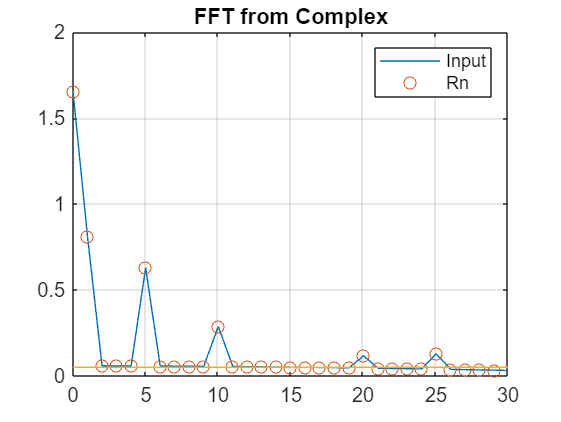

% Complex spectres
% complexSpectres.csv - In sign (real,imag), Imp (real, imag), Ref resistor
% sig (real, imag), Uz/Un (real,imag)
clear all
FFT_BUFFER_SIZE = 1024;
T = readtable('complexSpectres1024Hz1024.csv');
Yin_c = T{:,1}+1i*T{:,2};
Yimp_c = T{:,3}+1i*T{:,4};
Yref_c = T{:,5}+1i*T{:,6};
Y_in = abs(Yin_c)*2/FFT_BUFFER_SIZE; % they're maybe single sided - ARM FFT
Y_imp = abs(Yimp_c)*2/FFT_BUFFER_SIZE;
Y_ref = abs(Yref_c)*2/FFT_BUFFER_SIZE;
Y_in(1) = Y_in(1)/2;
Y_imp(1) = Y_imp(1)/2;
Y_ref(1) = Y_ref(1)/2;

N = 2*length(Yin_c);
fs = 1024;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

freq_detect_thres = 0.05;

figure()
plot(f_egy,Y_in);
hold on
% plot(f_egy,Y_imp); % no need to plot
scatter(f_egy,Y_ref);
plot(f_egy,ones(length(f_egy),1)*freq_detect_thres);
hold off
title('FFT from Complex')
legend('Input','Rn')
grid on
xlim([0,30])

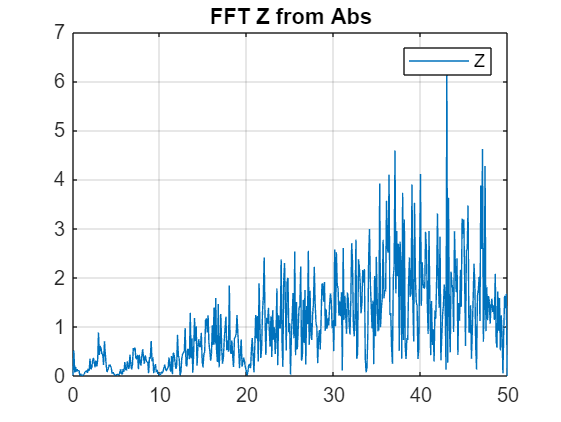

% Measured impedance spectre

% Ez most hülyeség, mert az impedancia jele is zaj

% Measure abs
clear all
T_a = readtable('absSpectres.csv');
T_c = readtable('complexSpectres.csv');
Z_a = T_a{:,4};

N = 2*length(Z_a);
fs = 100;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

% Plotting FFTs
figure()
plot(f_egy,Z_a);
xlim([0,50]);
title('FFT Z from Abs')
legend('Z')
grid on

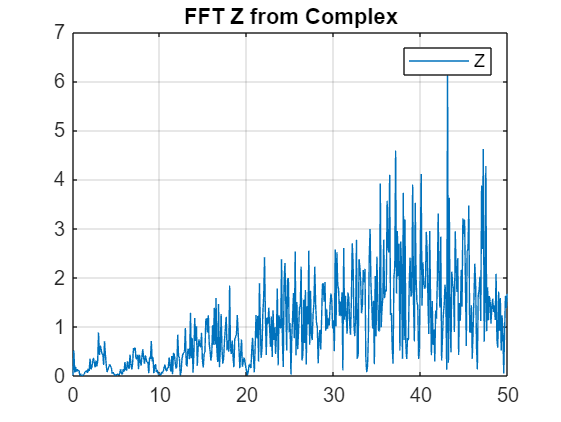


% Measured complex
FFT_BUFFER_SIZE = 1024;
T = readtable('complexSpectres.csv');
Z_c = T{:,7}+1i*T{:,8};
Z = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z(1) = Z(1)/2;

N = 2*length(Z_c);
fs = 100;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

figure()
plot(f_egy,Z);
title('FFT Z from Complex')
legend('Z')
grid on

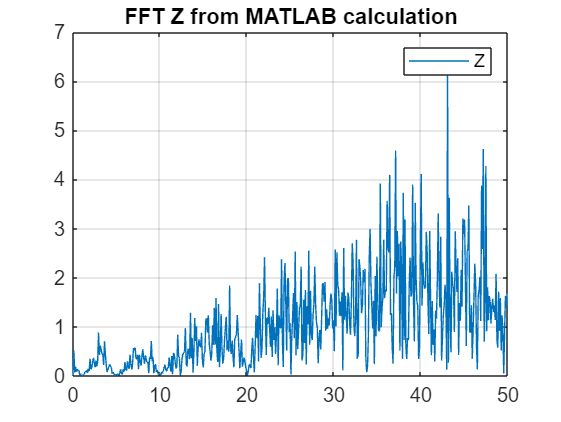


% Calculated in MATLAB
Yimp_c = T{:,3}+1i*T{:,4};
Yref_c = T{:,5}+1i*T{:,6};
Z_c_calc = Yimp_c./Yref_c;
Z_calc = abs(Z_c_calc)*2/FFT_BUFFER_SIZE;
Z_calc(1) = Z_calc(1)/2;

figure()
plot(f_egy,Z_calc);
title('FFT Z from MATLAB calculation')
legend('Z')
grid on


% MATLAB complex division result matches the calculated on the MCU, so the
% algorithm is okay